# Figure6: Tuning Curves

## 1. Setting up network

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures/Demo022722/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolderTC = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/SIEMt0.118_SEIMt2.028/']; % V1
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(DataFolderTC)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/']; % V1
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2';
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))
%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
%load("AllMFPixPara_Paper2TuneFig1V5D1.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all

AngleList = {'0.0','7.5','15.0','22.5'};
AngPrint = AngleList{1};
PlotUse = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang%s.mat',AngPrint)],'LDEEquv');
Patt = PlotUse.LDEEquv;
N_HCout = 4;

TruncList = 1; % of sigma
TruncInd = 1;
cmap = colormap("jet");

clear text

Creat new data

N_HCOut = 4;
for AngInd = 1:length(AngleList)
    FrTunCurAllPix = cell(NPixY,NPixX);
    for XX = 1:NPixX
        for YY = 1:NPixY
            FrTunCurAllPix{YY,XX}.S = zeros(8,1);
            FrTunCurAllPix{YY,XX}.C = zeros(8,1);
        end
    end

    AngPrint = AngleList{AngInd};
    PlotUse = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang%s.mat',AngPrint)],'LDEEquv');
    
    LDEOut = PlotUse.LDEEquv;
    LDEOutS = reshape(LDEOut.S,N_HCOut*NPixY,N_HCOut*NPixX);
    LDEOutC = reshape(LDEOut.C,N_HCOut*NPixY,N_HCOut*NPixX);
%     figure
%     ShowField(LDEOut.S*(1-CplxR) + LDEOut.C*CplxR,1:1600,40,40)
    for YInd = 1:NPixY
        for XInd = 1:NPixX
            y0 = NPixY+YInd; x0 = NPixX+XInd;
            % make sure this is in the center HC, so x0, y0 \in [11,20]
            %x0 = 11; y0 = 19; [13, 16] [14, 20]
            xC = NPixX*1.5+0.5; yC = NPixY*1.5+0.5;
            xx = x0-xC; yy = y0-yC; % centered
            RtPix = ...
                [xx,yy;
                yy,-xx;
                -xx,-yy;
                -yy,xx]; % rotational group
            SmPix = ...
                [-yy,-xx;
                -xx,yy;
                yy,xx;
                xx,-yy]; % Symmetry group
            PixAll = zeros(8,2);
            PixAll(1:2:7,:) = RtPix; PixAll(2:2:8,:) = SmPix;
            PixAllUse = floor(PixAll + repmat([xC,yC],8,1));
            for PixInd = 1:8
                FrTunCurAllPix{YInd,XInd}.S(PixInd) = ...
                    LDEOutS(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                FrTunCurAllPix{YInd,XInd}.C(PixInd) = ...
                    LDEOutC(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
            end
        end
    end
    
    save([SaveFolder sprintf('FrTuneCurE_Ang%s_CosAllNewSmear.mat',AngPrint)],'FrTunCurAllPix')
end

## 3*.1.1. Tuning curve for all

Any Pix

% fisrt load all data
FrTunCurveRawDataAll = cell(size(AngleList));
AngleAll = zeros(size(AngleList));
for AngInd = 1:length(AngleList)
    AngPrint = AngleList{AngInd};
    AngleAll(AngInd) = str2num(AngPrint);
    FrTunCurveRawDataAll{AngInd} = ...
        load([DataFolderTC sprintf('FrTuneCurE_Ang%s_CosAllNewSmear.mat',AngPrint)],'FrTunCurAllPix');
end

clearThree categories of pixels

[xAll,yAll] = meshgrid(1:10,1:10);
PixCtgr = cell(1,1);
xC = NPixX*.5+0.5; yC = NPixY*.5+0.5;% center
% get pix index for each categories
[PixCtgr{1}(:,1),PixCtgr{1}(:,2),~] = ...
    find( ...
    ( max(abs(xAll-xC),abs(yAll-yC)) == 4.5...%)); ...
    & max(abs(xAll-1), abs(yAll-1))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-1), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-1))>=2));
PixCtgr{1} = [
    PixCtgr{1};
    2,2;
    2,9;
    9,2;
    9,9];

% Do the 2*2 HC and print pixel texts
Fig5D = figure('Name','TuningCurves','units','normalized',...
    'outerposition',[0,0,0.32,0.35]);
HCPlot = subplot(1,3,1);
EPatt = Patt.S*(1-CplxR) + Patt.C*CplxR;
ShowField(EPatt, 1:NPixY*NPixX*N_HCout^2,NPixY*N_HCout,NPixX*N_HCout)
colorbar off

hold on
CtgrPix = PixCtgr{1};
CtgrPix(CtgrPix(:,1)>5 | CtgrPix(:,2)<=5,:) = [];
[~,a] = sort(CtgrPix(:,1)+CtgrPix(:,2));
CtgrPix = CtgrPix(a,:);
CtgrPix(2,:) = [];CtgrPix(end-1,:) = [];
PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel
MarkerList = {'*','o','+','x','s','^','p'};
LW = [2,1/2,2,1/2,2,1/2,2];

% get colors of the corresponding pixels
minv = min(EPatt);
maxv = max(EPatt);
ncol = size(cmap,1);
AllCs = round(1+(ncol-1)*(EPatt-minv)/(maxv-minv));

for PixInd = 1:length(CtgrPix)
    x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
    subplot(1,3,1);
    hold on
    txt = text(x+NPixX-0.3, y+NPixY+0.1, PixTxt(PixInd),...
        'FontSize',32,'FontWeight','bold');
    if PixInd == 1
        txt.Color = [1,1,1];
    end
end

txt =   Text (a) with properties:

                 String: 'a'
               FontSize: 32
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [1 1 1]
    HorizontalAlignment: 'left'
               Position: [10.7000 16.1000 0]
                  Units: 'data'

  Show all properties


txt =   Text (b) with properties:

                 String: 'b'
               FontSize: 32
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [10.7000 18.1000 0]
                  Units: 'data'

  Show all properties


txt =   Text (c) with properties:

                 String: 'c'
               FontSize: 32
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [11.7000 19.1000 0]
                  Units: 'data'

  Show all properties


txt =   Text (d) with properties:

                 String: 'd'
               FontSize: 32
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [12.7000 20.1000 0]
                  Units: 'data'

  Show all properties


txt =   Text (e) with properties:

                 String: 'e'
               FontSize: 32
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [14.7000 20.1000 0]
                  Units: 'data'

  Show all properties



PosA = get(HCPlot,'Position');
PosA(1) = PosA(1) - 0.09;
set(HCPlot,'Position',PosA)

cbar = colorbar; caxis([5 31])
set(cbar,'YTick',5:10:35,'FontSize',30)
axis([NPixX+.5 2*NPixX+.5 NPixX+.5 2*NPixY+.5])
axis off

TCPlot = subplot(1,3,[2,3]);
for PixInd = 1:length(CtgrPix)
    x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
    % get tuning curves
    [AngleData,TuningCurveTrunc,~,PreferAng] = TuningCurve(...
        TruncList,AngleList,FrTunCurveRawDataAll,...
        x,y,AngleAll,NPixX,NPixY,cmap);
    AngleCenter = PreferAng*180;
    
    
    subplot(1,3,[2,3]);
    hold on
    TunCurColor = cmap(AllCs(y+NPixY + (x+NPixX-1)*NPixY*N_HCout),:);
    % get unique data
    AngleUnique = unique(AngleData);
    TuningCurveUnique.S = zeros(size(AngleUnique));  
    TuningCurveUnique.C = zeros(size(AngleUnique));
    TuningCurvePlot.S = zeros(size(AngleUnique));  
    TuningCurvePlot.C = zeros(size(AngleUnique));

            1. Smooth the pumps; 2. recenter curves to 0 deg

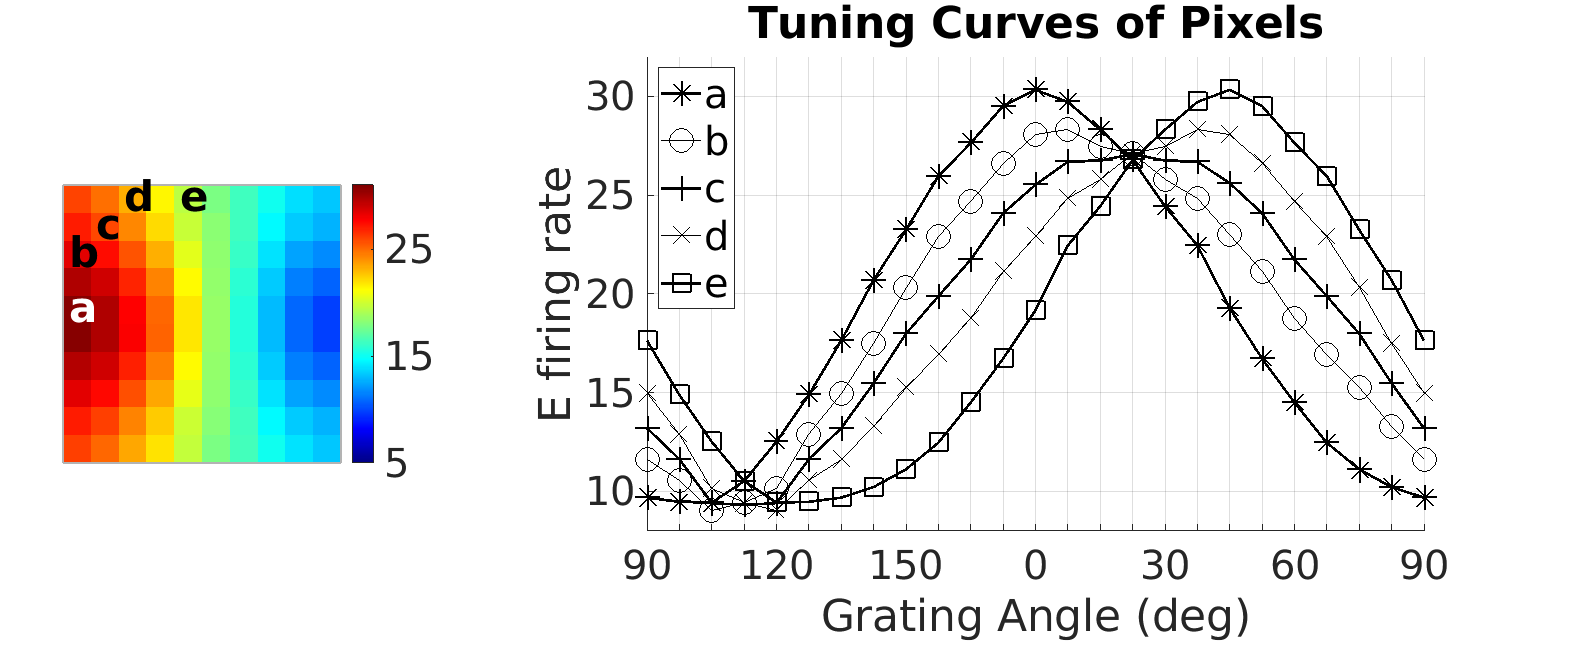

    for AngInd = 1:length(AngleUnique)
        Ang = AngleUnique(AngInd);
        TuningCurveUnique.S(AngInd) ...
            = mean(TuningCurveTrunc.S(AngleData==Ang,TruncInd),'all');
        TuningCurveUnique.C(AngInd) ...
            = mean(TuningCurveTrunc.C(AngleData==Ang,TruncInd),'all');
    end
    
    % note: length of AngleUnique should be odd!
    AnglePlot = [AngleUnique(floor(end/2)+1:end-1),...
                 AngleUnique(1:floor(end/2)), ...
                 AngleUnique(floor(end/2)+1)];
    for AngInd = 1:length(AnglePlot)
        Ang = AnglePlot(AngInd);
        TuningCurvePlot.S(AngInd) ...
            = mean(TuningCurveUnique.S(AngleUnique==Ang),'all');
        TuningCurvePlot.C(AngInd) ...
            = mean(TuningCurveUnique.C(AngleUnique==Ang),'all');
    end
    
    textPlot = mat2cell(repmat(PixTxt(PixInd),1,length(AngleUnique)),1,ones(size(AngleUnique)));
    
    plot(AngleUnique,TuningCurvePlot.S*0.7 + ...
        TuningCurvePlot.C*0.3,'k','LineWidth',LW(PixInd),...)
       ...% 'Color',TunCurColor,
        'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd},...
        'MarkerSize',18)
%     text(AngleUnique,TuningCurvePlot.S*0.7 + ...
%         TuningCurvePlot.C*0.3-0.5,...
%         textPlot, 'HorizontalAlignment','center', 'VerticalAlignment','bottom')

end

% set appropirate xticks and others
xtickAng = AnglePlot;
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,4) == 1
        xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

PosB = get(TCPlot,'Position');
PosB(2) = PosB(2) +0.1; PosB(4) = PosB(4) - 0.11;
set(TCPlot,'Position',PosB)

set(TCPlot,'FontSize',30)
xlabel('Grating Angle (deg)','FontSize',33); 
ylabel('E firing rate','FontSize',33)
title('Tuning Curves of Pixels','FontSize',33)

ylim([8 32]); xlim([0 180])
set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
%set(gca, 'FontSize',14)
grid on
%xlim([min(xtickAng) max(xtickAng)])
legend('Location','northwest','FontSize',30)

Save figures

FigName1 = sprintf('Figure5DDraft');
savefig(Fig5D,[FigurePaperPath FigName1 '.fig']);


Print Figs

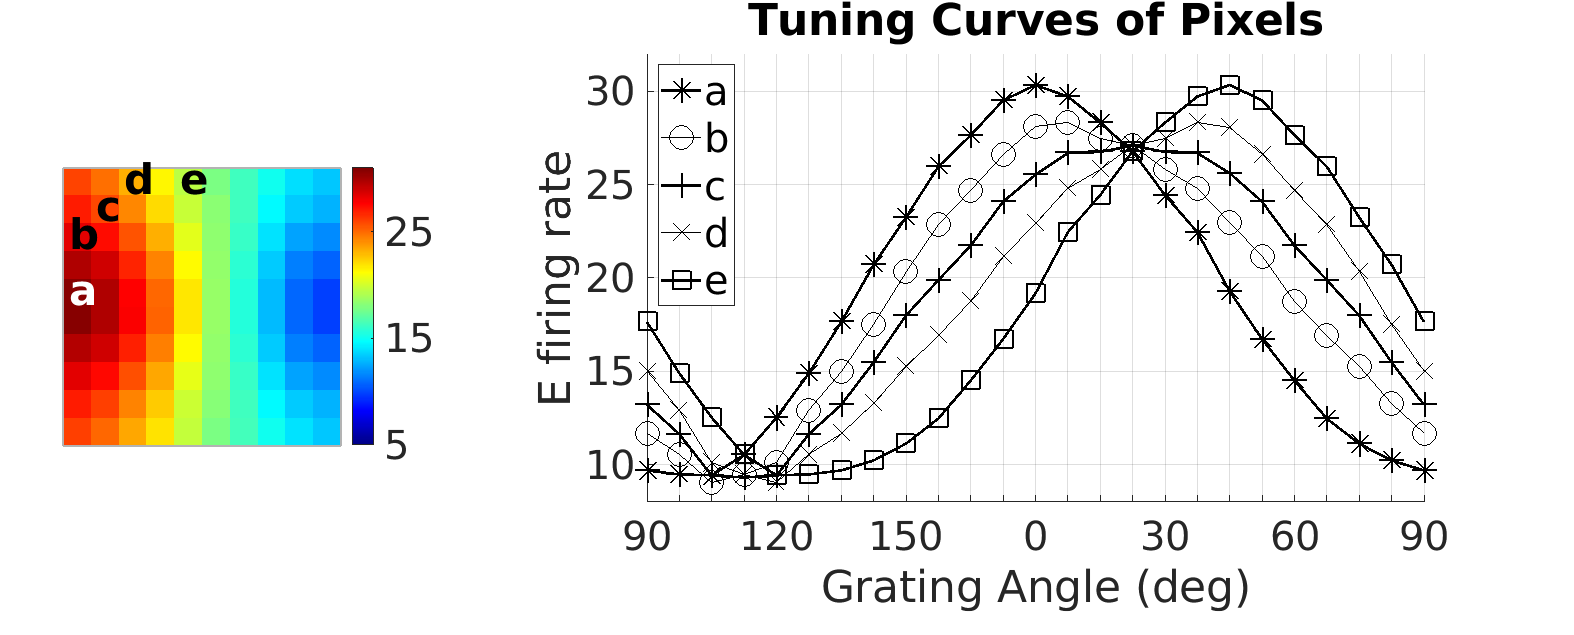

Fig5D.PaperUnits = 'centimeters';
Fig5D.PaperSize = [70,25];
Fig5D.PaperOrientation = "landscape";
exportgraphics(Fig5D,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)